Open Loop step Response

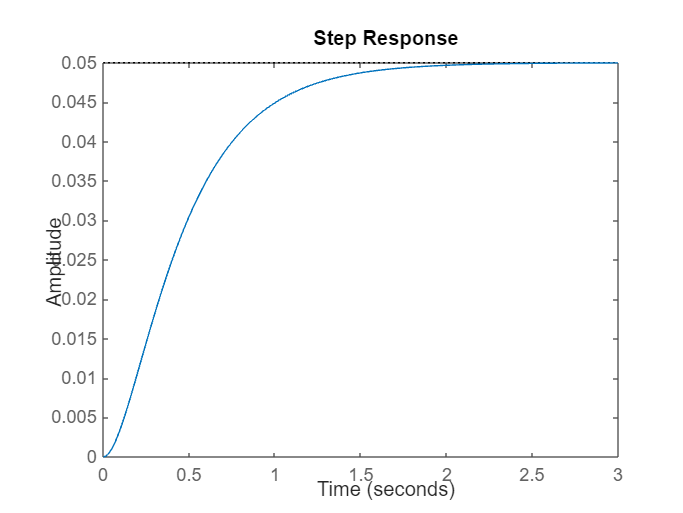

s = tf('s');
P = 1/(s^2 + 10*s + 20);
step(P)

設計一個控制器 減少上升時間、穩定時間、消除穩態誤差

比例控制器(Kp)，減少上升時間，增加超調，減少穩態誤差

讓比例增益(Kp)等於300

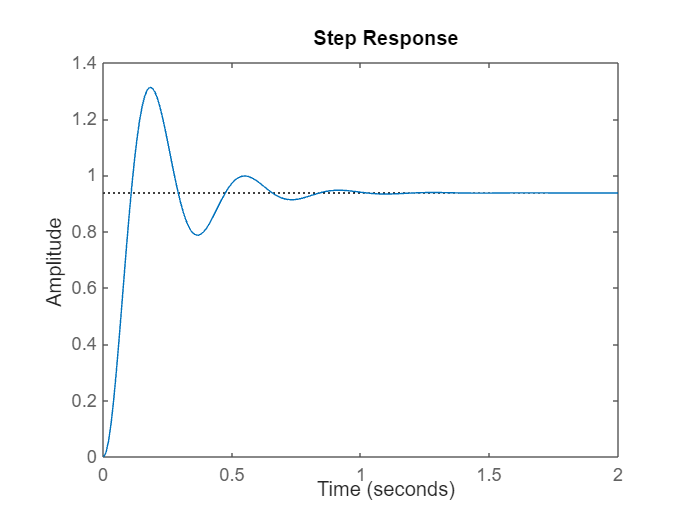

Kp = 300;
C = pid(Kp);
T = feedback(C*P, 1);

t = 0 : 0.01 : 2;
step(T, t)

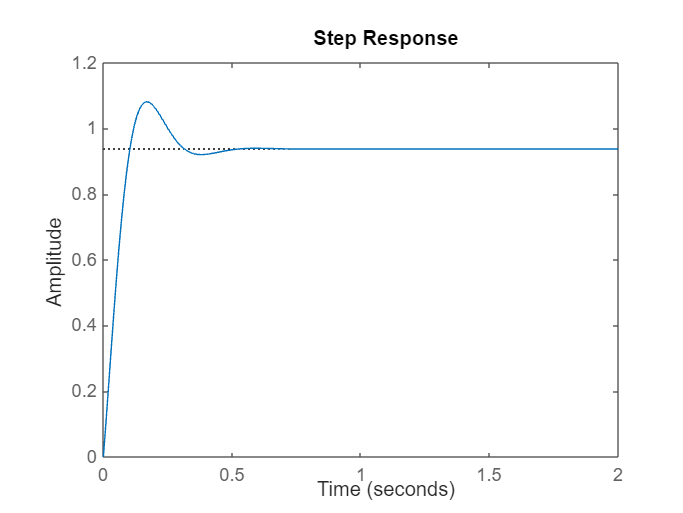

% Kd = 10
Kp = 300;
Kd = 10;
C = pid(Kp, 0, Kd);
T = feedback(C * P, 1);

t = 0:0.01:2;
step(T, t)

Kp 減少至 30，Ki 等於 70;

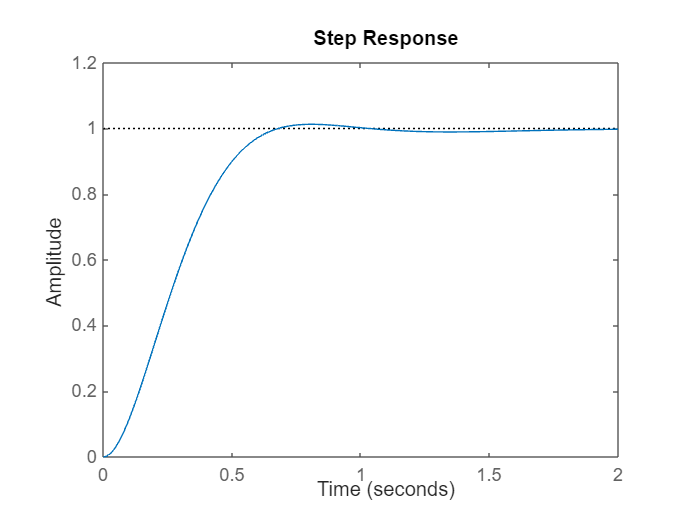

Kp = 30;
Ki = 70;
C = pid(Kp, Ki);
T = feedback(C * P, 1);

t = 0:0.01:2;
step(T, t)

對於此系統的最佳化

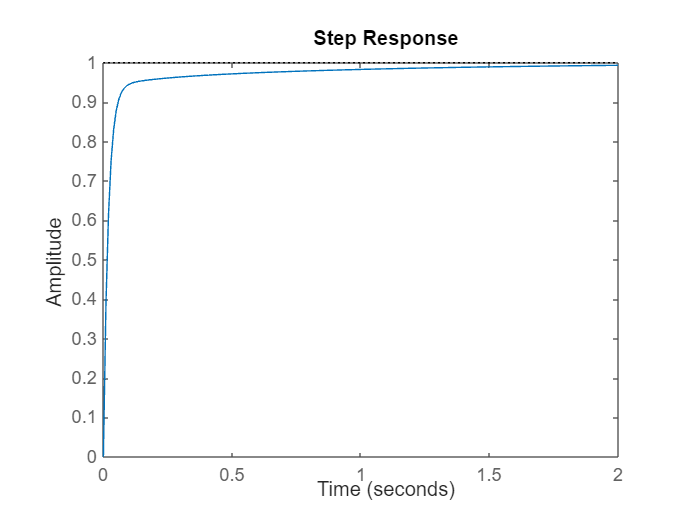

Kp = 350;
Ki = 300;
Kd = 50;

C = pid(Kp, Ki, Kd);
T = feedback(C * P, 1);

t = 0:0.01:2;
step(T, t)

pidtune / pidTuner

pidTuner(P, 'p');

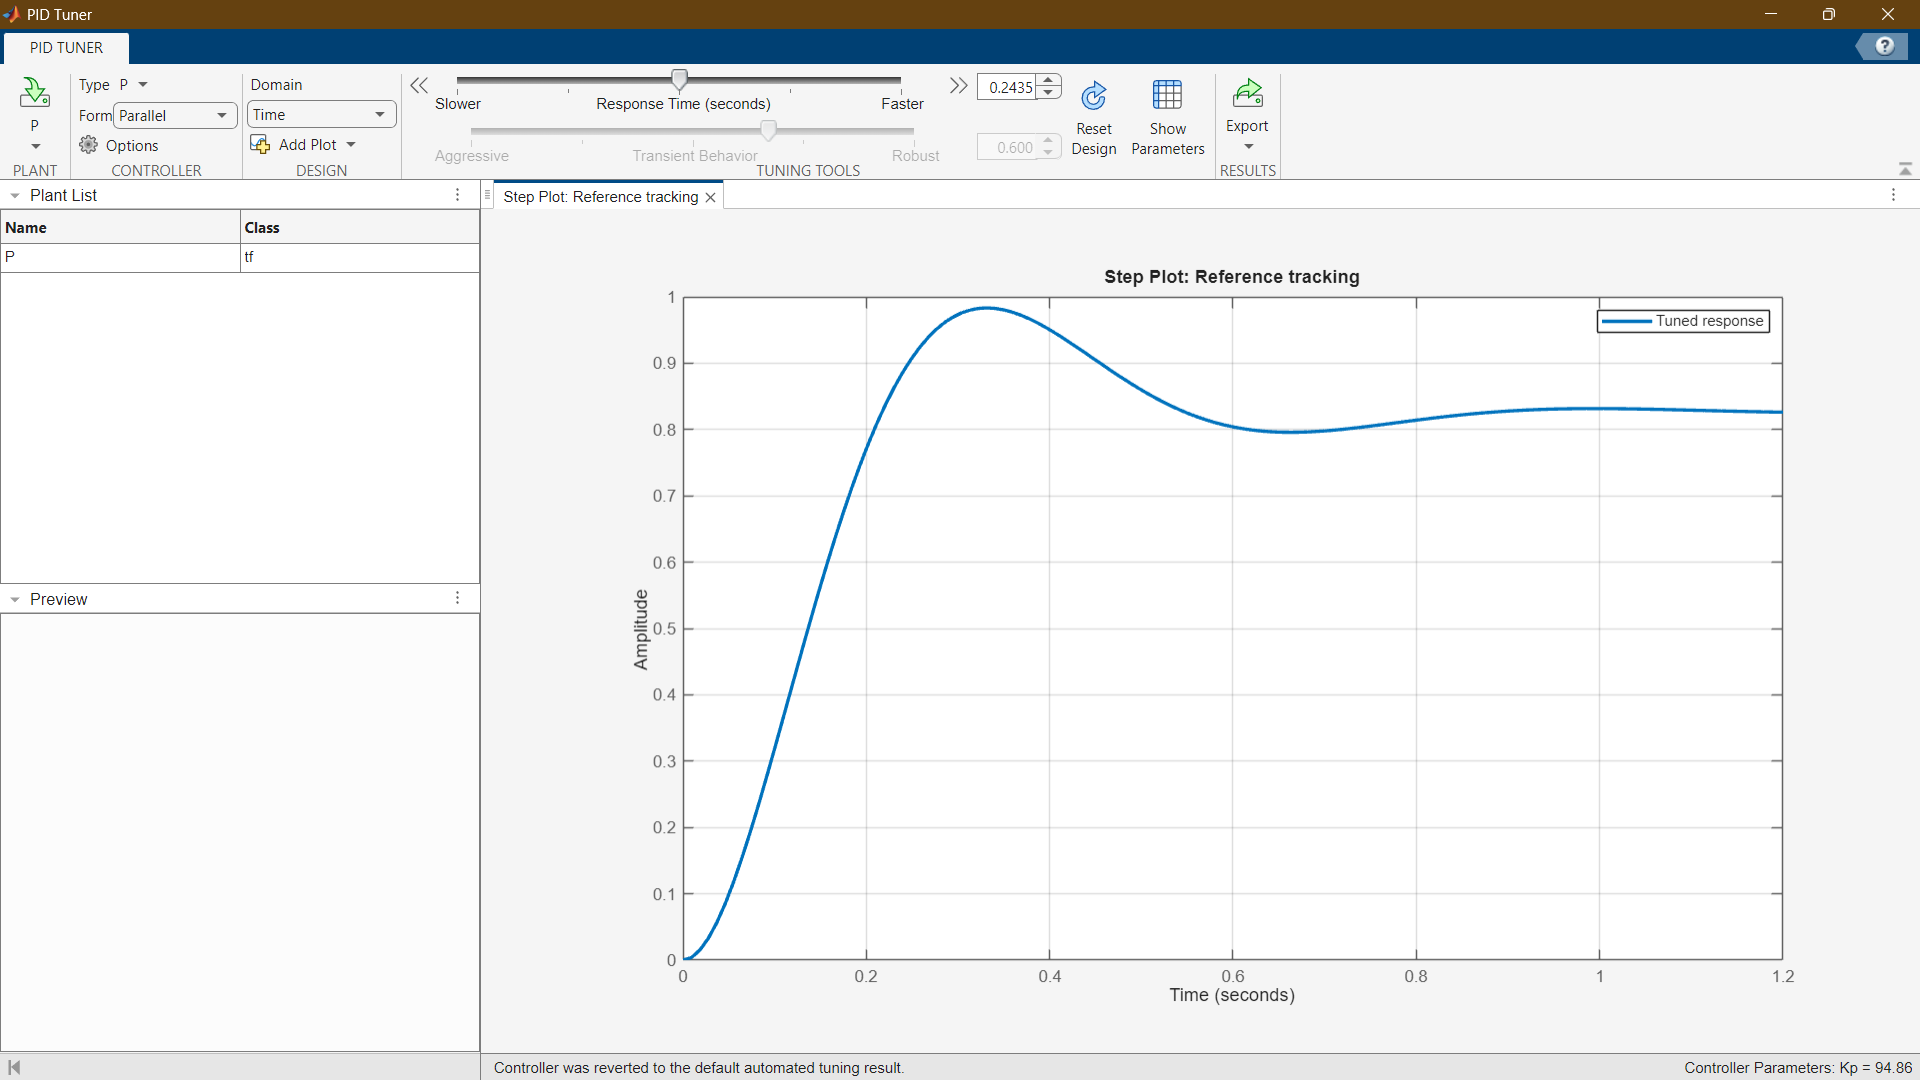

pidTuner(P, C);

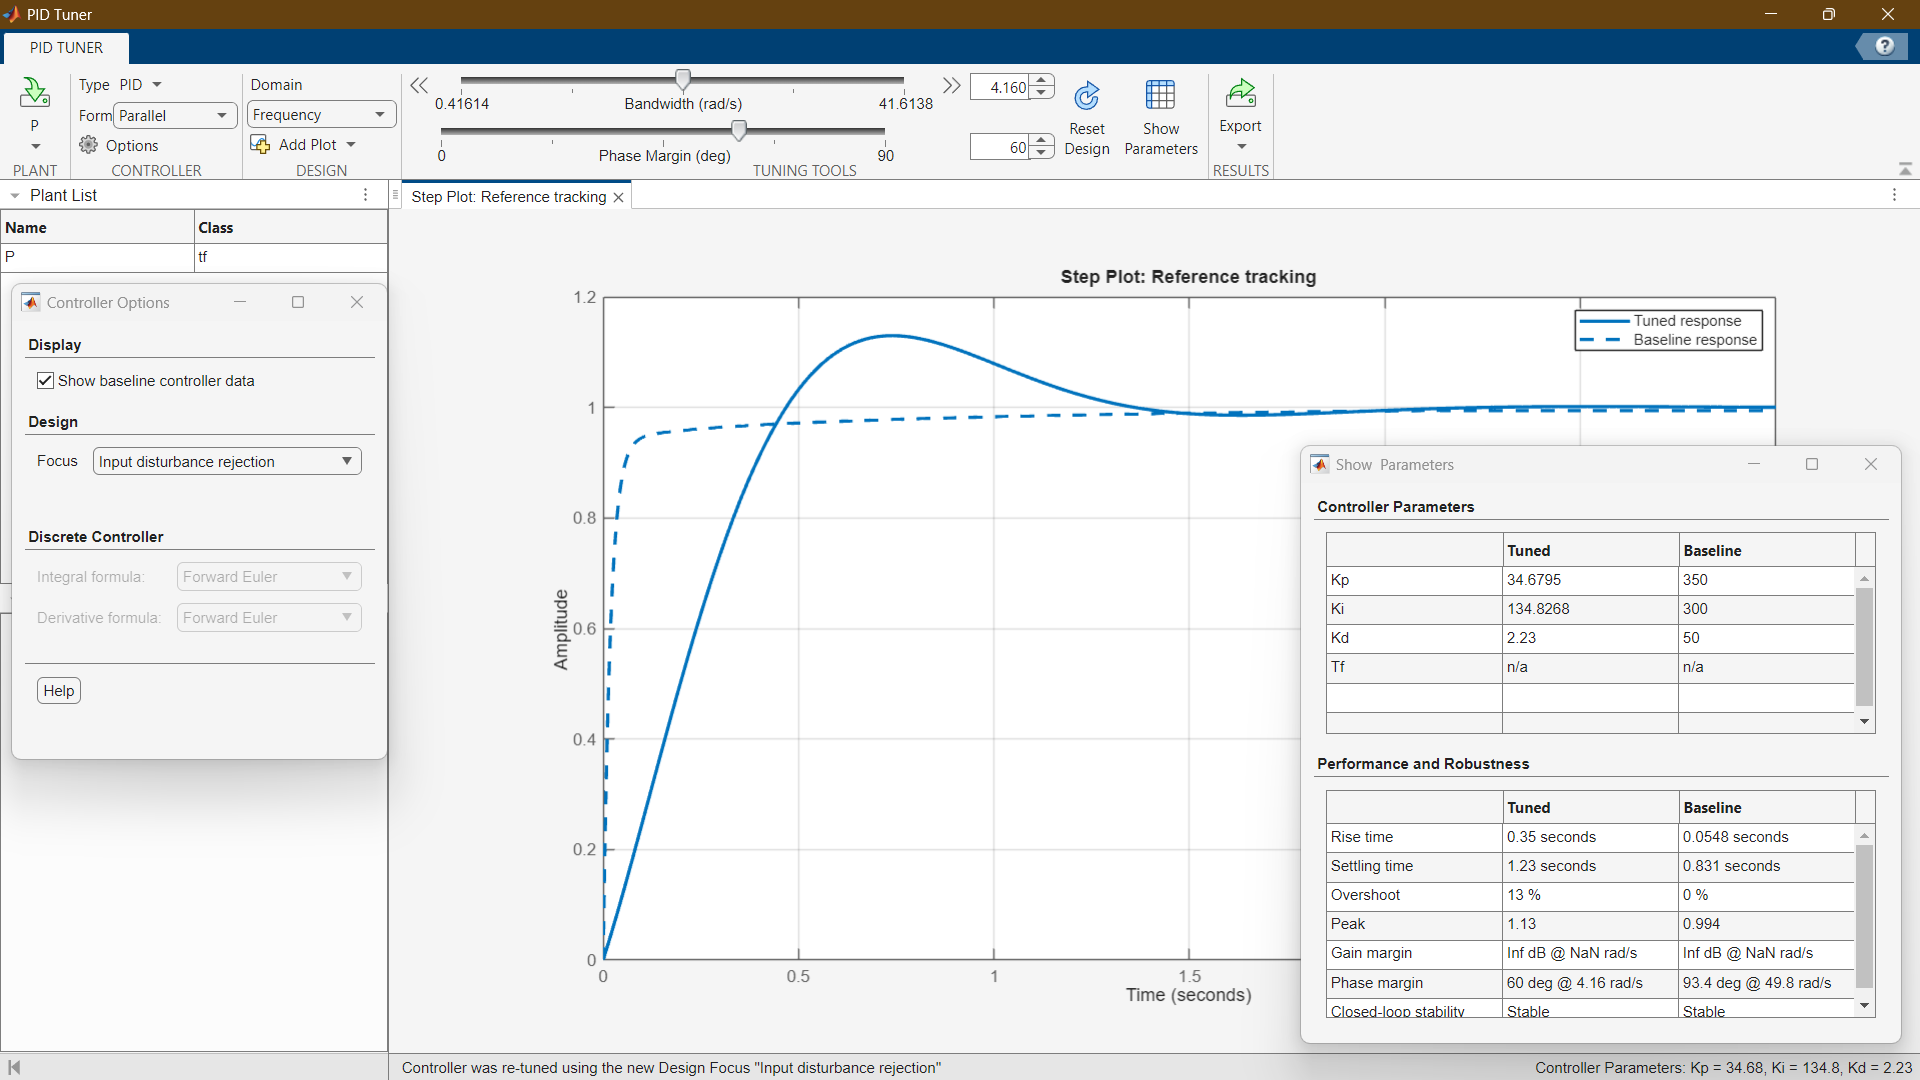

opts = pidtuneOptions('CrossoverFrequency', 32, 'PhaseMargin', 90);
[C, info] = pidtune(P, 'pid', opts)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 320, Ki = 796, Kd = 32.2
 
Continuous-time PID controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 32
           PhaseMargin: 90
